# dayplotter

clearvars -except kg kg2 hkg hkg2 dark light darkmulti lightmulti %clear variables that aren't giant structures

# single fish

Average amplitude range figure

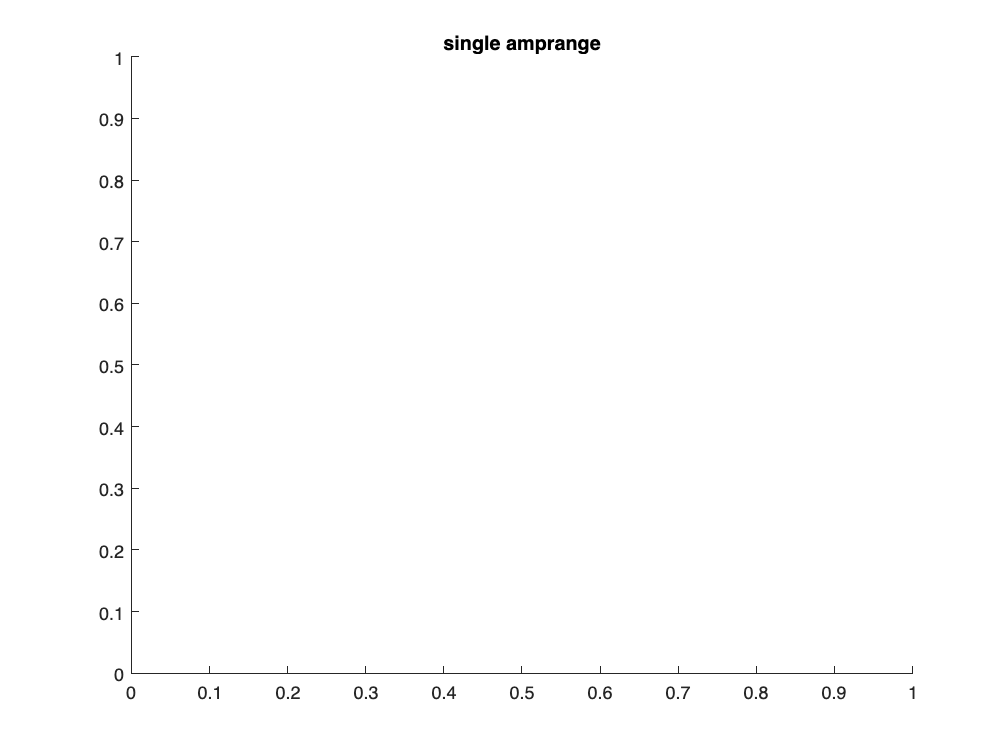

figure(89); clf; title('single amprange'); hold on;


    for j = 1:length(dark)

        ld(j,:) = dark(j).ld;
       
        for kk = 1:length([dark(j).fish])
            clrbyfish = hsv(length(dark(j).fish));
            for jj = 1:length(dark(j).fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld(j,:), dark(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end
       
        plot(ld(j,:), dark(j).exp.expavgrange, 'k.', 'MarkerSize', 35);

    end

Unrecognized function or variable 'dark'.

   %set(gca,'xscale', 'log', 'yscale', 'log');

figure(90); clf; title('singe hour amprange'); hold on;

 for j = 11

        ld(j,:) = dark(j).ld;
       
        for kk = 1:length([dark(j).fish])
            clrbyfish = hsv(length(dark(j).fish));
            for jj = 1:length(dark(j).fish(kk).amprange)
          %  plot(ld(j,:), dark(j).fish(kk).amprange(jj), clrbyfish(kk,:),'.', 'MarkerSize', 8, 'DisplayName', num2str(kk));
            scatter(ld(j,:), dark(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
           % label(kk,:) = num2str(kk);
          
            end 
             legend;
        end
       % legend;
        plot(ld(j,:), dark(j).exp.expavgrange, 'k.', 'MarkerSize', 35);
hold off
legend show
 end

Daymean average

figure(317); clf; title('Dark to Light day mean single'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

clrs = k_colormefriendly;

    for j = 1:length(dark)
   
        ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * dark(j).ld);
        p(j) = plot((dark(j).exp.hourtim .* crosshour)-pi, dark(j).exp.meanofexperimentmeans, 'LineWidth', 2.5,'Color', clrs(j,:));
        
         legend(num2str(ld)); 
        legend('AutoUpdate', 'off'); 
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);

# multifish

figure(98); clf; title('multi amprange'); hold on;

    for j = 1:length(darkmulti)

        ld(j,:) = darkmulti(j).ld;
       
        for kk = 1:length([darkmulti(j).fish])
            clrbyfish = hsv(length(darkmulti(j).fish));
            for jj = 1:length(darkmulti(j).fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld(j,:), darkmulti(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end
       
        plot(ld(j,:), darkmulti(j).exp.expavgrange, 'k.', 'MarkerSize', 35);

    end
   %set(gca,'xscale', 'log', 'yscale', 'log');

Daymean average

figure(316); clf; title('Dark to Light day mean multi'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

clrs = k_colormefriendly;

    for j = 1:length(darkmulti)
   
        ld(j,:) = darkmulti(j).ld;
        crosshour = (2*pi) / (2 * darkmulti(j).ld);
        p(j) = plot((darkmulti(j).exp.hourtim .* crosshour)-pi, darkmulti(j).exp.meanofexperimentmeans, 'LineWidth', 2.5,'Color', clrs(j,:));
        
         legend(num2str(ld)); 
        legend('AutoUpdate', 'off'); 
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);